# Substation maintenance scheduling

## Summary

In this use case, electrical substation maintenance spots without service disruption are found and classified based on the electric consumption rates of 100 sites of different industries.

## 1. Clustering the data

The data does not contain substation information, so it is assumed a total of 5 substations. The location of these substations are determined based on the proximity in latitude and longitude of the sites under study. The substations are assumed to be located in the centroid of the result of a K-means clustering of the sites.

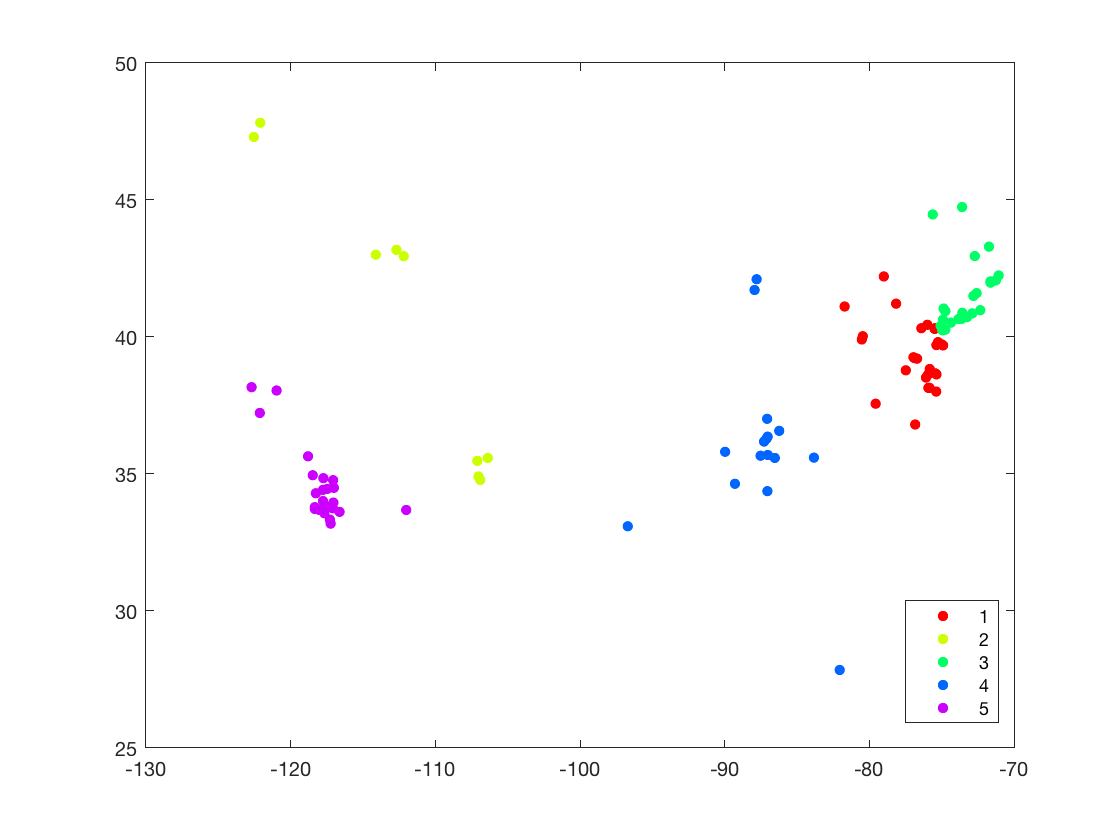

% Reading the data
ReadAllMetadata
load preprocessed-data/preprocessed-timeseries.mat

X = allsites{:,{'LAT','LNG'}};
[idx, C] = kmeans(X,5);

figure;
gscatter(X(:,1),X(:,2),idx);
view(90,-90);

## 2. Maintenance Spots

In a second step the electric consumption of the sites belonging to the same cluster is aggregated. Based on this aggregated consumption per substation, the max peak power consumption is randomly established by multiplying the maximum power consumption during the year, with a random percentage between 5% and 35%.

The suitable maintenance spots are determined using the aggregated electric consumption, the peak power consumption and a user specified threshold of the percentage of the substation that needs to be shut down while being repaired. A suitable maintenance spot is the one where the average consumption is lower than the max peak consumption multiplied by the mentioned user-defined percentage.

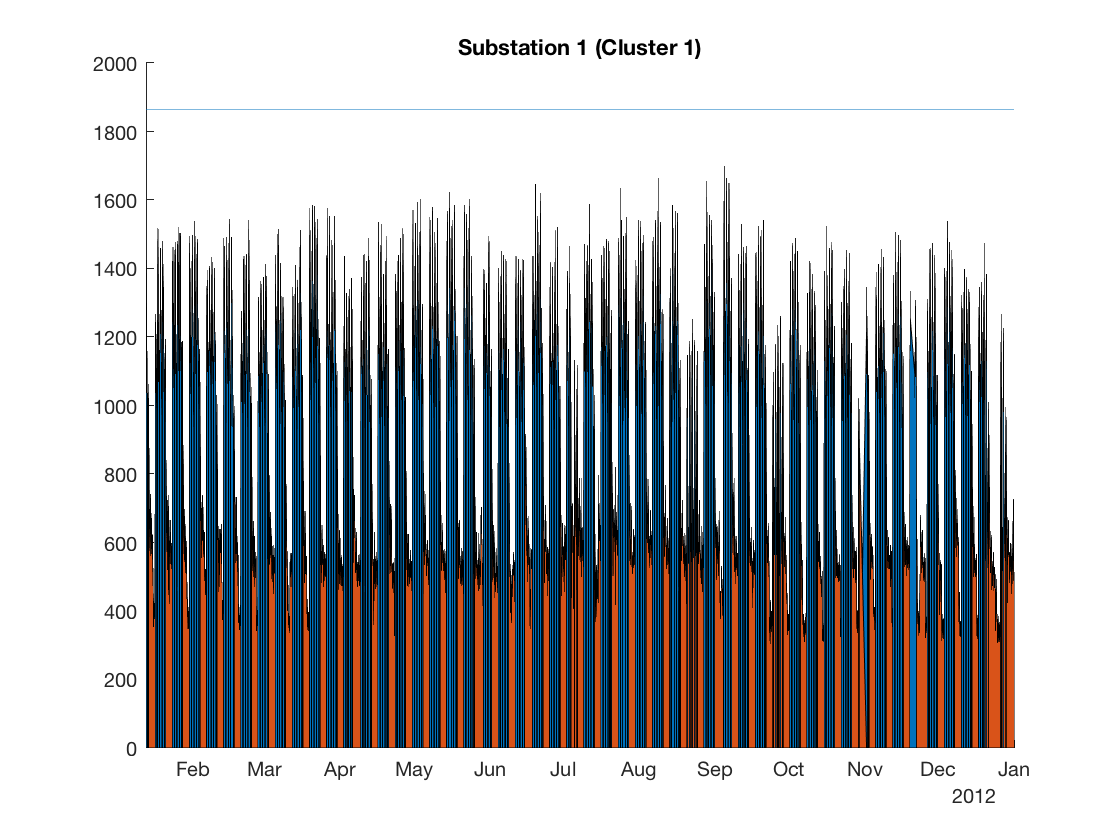

% Aggregated consumption per cluster
load preprocessed-data/preprocessed.mat data
datestime = datetime(Mts(1).time,'ConvertFrom', 'posixtime');

cluster1 = data(:,idx==1);
cluster2 = data(:,idx==2);
cluster3 = data(:,idx==3);
cluster4 = data(:,idx==4);
cluster5 = data(:,idx==5);

aggCluster1 = sum(cluster1,2);
aggCluster2 = sum(cluster2,2);
aggCluster3 = sum(cluster3,2);
aggCluster4 = sum(cluster4,2);
aggCluster5 = sum(cluster5,2);

% Set a random maximum capacity for the imaginary electrical station supplying a given cluster
a = 1.05;
b = 1.35;
r = (b-a).*rand(1,'single') + a;
maxCluster1 = max(aggCluster1) * r;
r = (b-a).*rand(1,'single') + a;
maxCluster2 = max(aggCluster2) * r;
r = (b-a).*rand(1,'single') + a;
maxCluster3 = max(aggCluster3) * r;
r = (b-a).*rand(1,'single') + a;
maxCluster4 = max(aggCluster4) * r;
r = (b-a).*rand(1,'single') + a;
maxCluster5 = max(aggCluster5) * r;

threshold = 0.5;

figure;
line([datestime(1), datestime(end)], [maxCluster1, maxCluster1]);
hold on;
% Greater than threshold of the max peak consumption
area(datestime, aggCluster1 .* (aggCluster1 > (threshold * maxCluster1)));
hold on;
% Lower or equal than threshold of the max peak consumption
area(datestime, aggCluster1 .* (aggCluster1 <= (threshold * maxCluster1)));
xlim([datestime(1), datestime(end)])
title('Substation 1 (Cluster 1)');

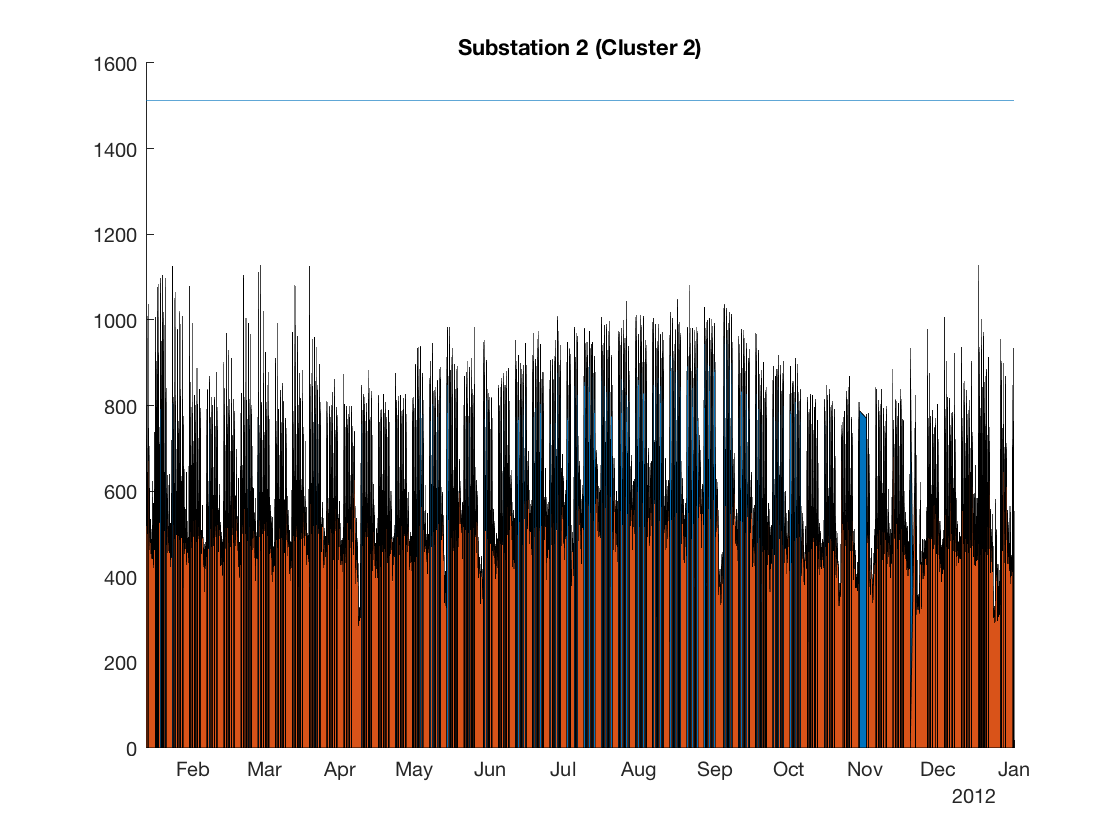


figure;
line([datestime(1) datestime(end)], [maxCluster2, maxCluster2]);
hold on;
% Greater than threshold of the max peak consumption
area(datestime, aggCluster2 .* (aggCluster2 > (threshold * maxCluster2)));
hold on;
% Lower or equal than threshold of the max peak consumption
area(datestime, aggCluster2 .* (aggCluster2 <= (threshold * maxCluster2)));
xlim([datestime(1) datestime(end)])
title('Substation 2 (Cluster 2)');

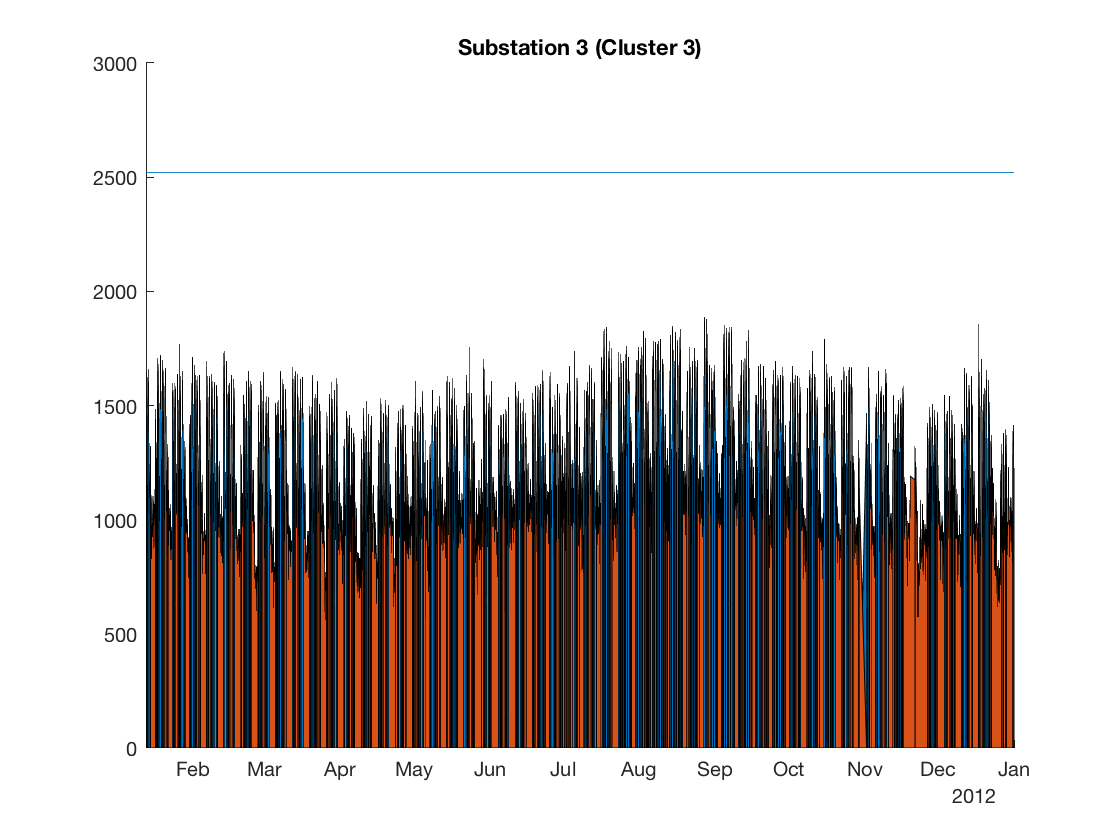


figure;
line([datestime(1) datestime(end)], [maxCluster3, maxCluster3]);
hold on;
% Greater than threshold of the max peak consumption
area(datestime, aggCluster3 .* (aggCluster3 > (threshold * maxCluster3)));
hold on;
% Lower or equal than threshold of the max peak consumption
area(datestime, aggCluster3 .* (aggCluster3 <= (threshold * maxCluster3)));
xlim([datestime(1) datestime(end)])
title('Substation 3 (Cluster 3)');

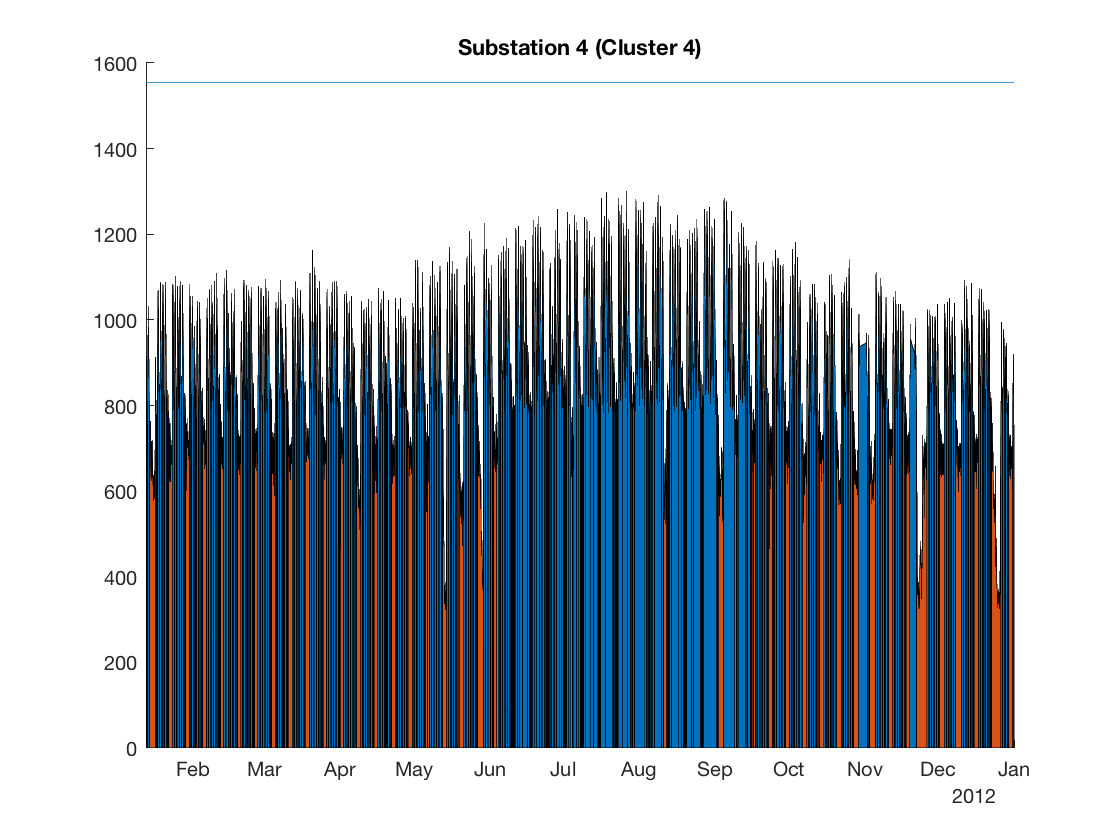


figure;
line([datestime(1) datestime(end)], [maxCluster4, maxCluster4]);
hold on;
% Greater than threshold of the max peak consumption
area(datestime, aggCluster4 .* (aggCluster4 > (threshold * maxCluster4)));
hold on;
% Lower or equal than threshold of the max peak consumption
area(datestime, aggCluster4 .* (aggCluster4 <= (threshold * maxCluster4)));
xlim([datestime(1) datestime(end)])
title('Substation 4 (Cluster 4)');

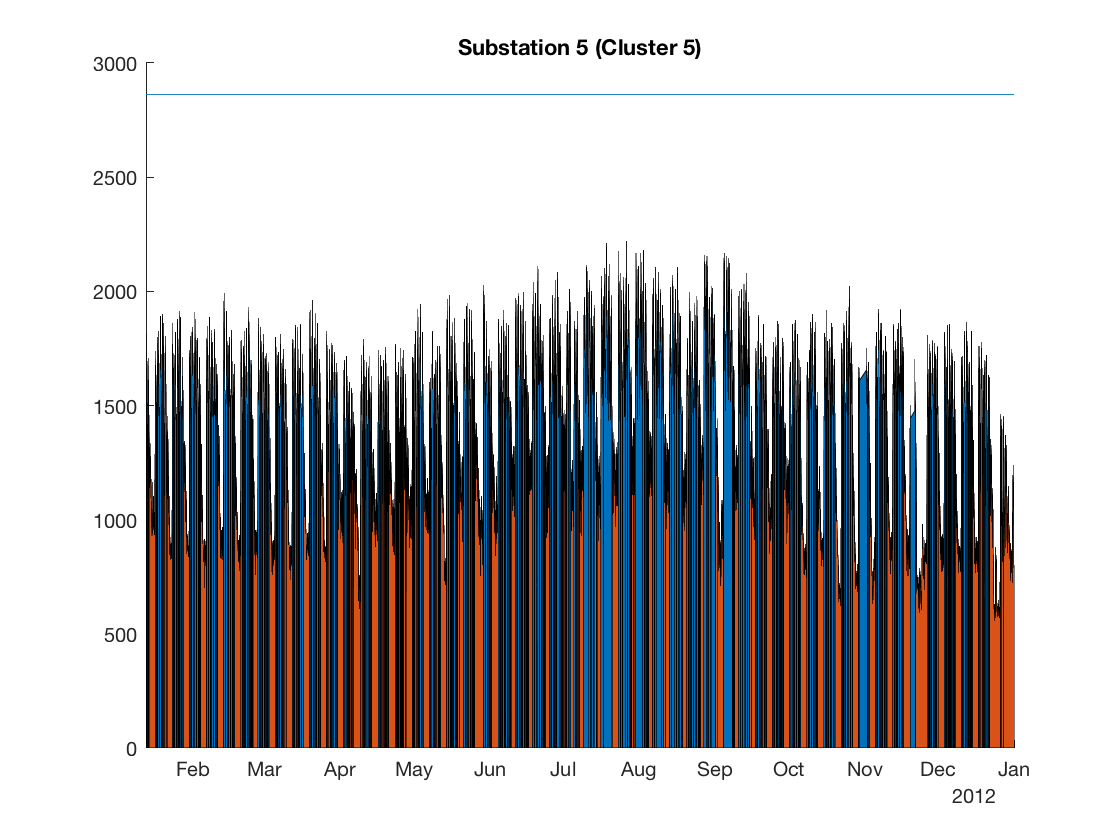


figure;
line([datestime(1) datestime(end)], [maxCluster5, maxCluster5]);
hold on;
% Greater than threshold of the max peak consumption
area(datestime, aggCluster5 .* (aggCluster5 > (threshold * maxCluster5)));
hold on;
% Lower or equal than threshold of the max peak consumption
area(datestime, aggCluster5 .* (aggCluster5 <= (threshold * maxCluster5)));
xlim([datestime(1) datestime(end)])
title('Substation 5 (Cluster 5)');

## Let's explore the dates suitable for maintenance windows

Having the suitable maintenance time slots for each of the substations, a further filtering step is applied. In this filtering, the user specifies the required maintenance time, which will be determined by the work to be applied to the substation.

A decision tree classification ensemble is applied to explain when to operate the substations without compromising the service. This is done using the maintenance slots of the required time and a decomposition of the date into:

- Day

- Hour

- Minute

- Week of the month

- Month

- Is Weekend? Boolean value denoting whether the maintenance slot occurs in a weekend or not.

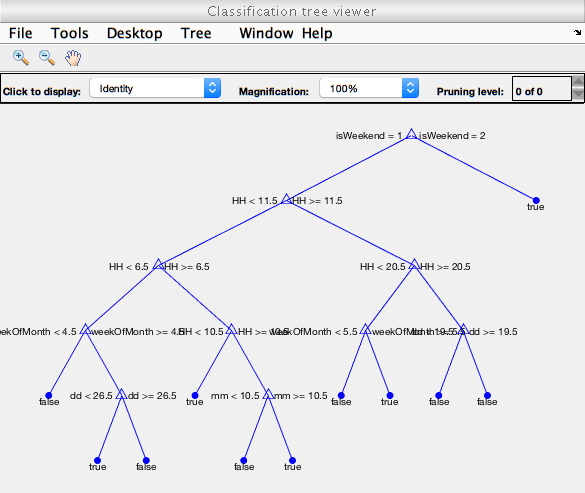

% User specified parameter with the required maintenance hours
requiredMaintenanceHours = 1;

d = diff(aggCluster1 <= (threshold * maxCluster1));
e = d(d~=0);
d = [0; d]; d(end)=-1*e(end);
startCluster1 = datestime(d==1);
endCluster1 = datestime(d==-1);

durationCluster1 = endCluster1 - startCluster1;
startCluster1 = startCluster1(durationCluster1 > hours(requiredMaintenanceHours));
endCluster1 = endCluster1(durationCluster1 > hours(requiredMaintenanceHours));

isWeekend = isweekend(datestime);
isBusinessDay = isbusday(datestime);
mm = month(datestime);
weekOfMonth = week(datestime, 'weekofmonth');
dd = day(datestime);
HH = hour(datestime);
MM = minute(datestime);
X = table(isWeekend, mm, weekOfMonth, dd, HH, MM);
Y = aggCluster1 <= (threshold * maxCluster1);

Z = false(length(datestime),1);
for i = 1:length(startCluster1)
    Z = Z | isbetween(datestime, startCluster1(i), endCluster1(i));
end

Y = Y & Z;

t = fitcensemble(X,Y,'Method','RobustBoost');
t.Trained{1}.view('Mode','graph');


T = logical(predict(t.Trained{1}, X));



Exploring the tree the **best candidate maintenance windows** for the **substation 1** are:

- **Weekends at any time.**

- **Working days between 6am and 10 am**

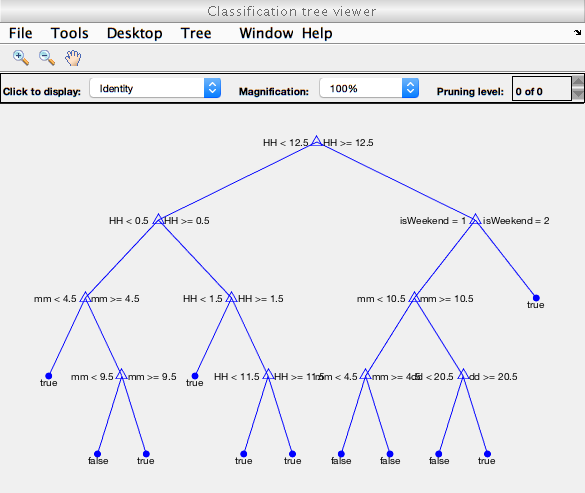

% User specified parameter with the required maintenance hours
requiredMaintenanceHours = 1;

d = diff(aggCluster2 <= (threshold * maxCluster2));
e = d(d~=0);
d = [0; d]; d(end)=-1*e(end);
startCluster2 = datestime(d==1);
endCluster2 = datestime(d==-1);

durationCluster2 = endCluster2 - startCluster2;
startCluster2 = startCluster2(durationCluster2 > hours(requiredMaintenanceHours));
endCluster2 = endCluster2(durationCluster2 > hours(requiredMaintenanceHours));

isWeekend = isweekend(datestime);
isBusinessDay = isbusday(datestime);
mm = month(datestime);
weekOfMonth = week(datestime, 'weekofmonth');
dd = day(datestime);
HH = hour(datestime);
MM = minute(datestime);
X = table(isWeekend, mm, weekOfMonth, dd, HH, MM);
Y = aggCluster2 <= (threshold * maxCluster2);

Z = false(length(datestime),1);
for i = 1:length(startCluster2)
    Z = Z | isbetween(datestime, startCluster2(i), endCluster2(i));
end

Y = Y & Z;

t = fitcensemble(X,Y,'Method','RobustBoost');
t.Trained{1}.view('Mode','graph');

Exploring the tree the **best candidate maintenance windows** for the **substation 2** are:

- **Weekends from 1pm.**

- **Any day between 1am and 11am.**